# Bernstein Polynomials: Properties.

A Bernstein polynomial of order N is defined as 


$$x_N(t) = \sum_{i=0}^N{\bar{x}_{i,N}b_{i,N}\left(t\right)}, \quad t \in [0, t_f]$$


where $\bar{x}_{i,N} \in \mathbb{R}$ is the Bernstein coefficient and $b_{i,N}(t)$is the Bernstein polynomials basis defined as

 
$$b_{i,N}(t) = \left( \begin{array}{c} N \\ i \end{array} \right) \frac{ t^i (t_f-t)^{N-i} }{ t_f^n }, $$


where 


$$ \left( \begin{array}{c} N \\ i \end{array} \right) = \frac{N!}{i!(N-i)!}$$


is the binomial coefficient. Notice that, for a given range of argument $[0,t_f]$, Bernstein polynomials are uniquely defined by the Bernstein coefficients: unlike Lagrange polynomials, Bernstein polynomials do NOT satisfy the Kronecker property and they are NOT interpolating polynomials. Bernstein polynomials were popularized by Pierre Bezier in the early 1960s as useful tools for geometric design (Bezier used 2D and 3D Bernstein polynomials to design the shape of the cars at the Renault company in France), and are now widely used in computer graphics, animations, and type fonts such as postscript fonts and true type fonts. For this reason, Bernstein polynomials are often referred to as a Bezier curves, especially when used to describe spatial curves.

Bernstein polynomials possess favorable geometric and numerical properties that can be exploited in many application domains, including motion planning and trajectory generation. In this document, we state the main properties of Bernstein polynomials and present the BeBOT MATLAB toolkit, where these properties are implemented. The following figures are examples of 1D, 2D and 3D Bernstein polynomials.

## Examples of 1,2,3D Bernstein polynomials

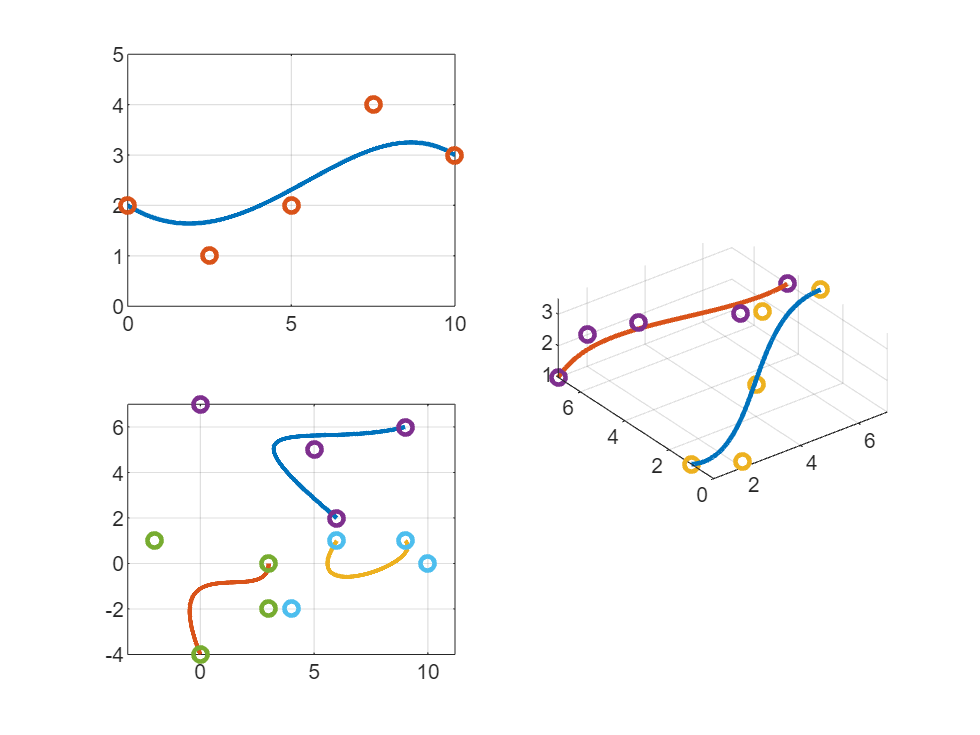

clear all
close all

tf = 10;
t = linspace(0,tf,1000);

% 1D Bernstein Polynomial
x_N = [2 1 2 4 3];
xN = BernsteinPoly(x_N,t);

% 2D Bernstein Polynomials
x1_N = [6 0 5 9; 2 7 5 6];
x2_N = [0 -2 3 3; -4 1 -2 0];
x3_N = [6 4 10 9; 1 -2 -0 1];
x1N = BernsteinPoly(x1_N,t);
x2N = BernsteinPoly(x2_N,t);
x3N = BernsteinPoly(x3_N,t);

% 3D Bernstein Polynomials
p1_N = [1,2,4,5,7; 1,0,2,3,3; 1,1.2,2,3.5,3.5];
p2_N = [1,2,3,5,7; 7,7,6,4,4.5; 1,2,2.5,3,3];
p1N = BernsteinPoly(p1_N,t);
p2N = BernsteinPoly(p2_N,t);

% Plot the polynomials above
figure
subplot(2,2,1);
plot(t,xN,'LineWidth',2); hold on
plot(linspace(0,tf,length(x_N)),x_N,'o','LineWidth',2);
axis([0 10 0 5])
grid on
subplot(2,2,3)
plot(x1N(1,:),x1N(2,:),'LineWidth',2); hold on
plot(x2N(1,:),x2N(2,:),'LineWidth',2);
plot(x3N(1,:),x3N(2,:),'LineWidth',2);
plot(x1_N(1,:),x1_N(2,:),'o','LineWidth',2);
plot(x2_N(1,:),x2_N(2,:),'o','LineWidth',2);
plot(x3_N(1,:),x3_N(2,:),'o','LineWidth',2);
axis equal
grid on
subplot(2,2,[2,4])
plot3(p1N(1,:),p1N(2,:),p1N(3,:),'LineWidth',2); hold on
plot3(p2N(1,:),p2N(2,:),p2N(3,:),'LineWidth',2);
plot3(p1_N(1,:),p1_N(2,:),p1_N(3,:),'o','LineWidth',2);
plot3(p2_N(1,:),p2_N(2,:),p2_N(3,:),'o','LineWidth',2);
axis equal
grid on

## End point value property

The Bernstein polynomial 


$$$x_N(t) = \sum_{j=0}^N \bar{x}_{j,N} b_{j,N}(t)$  $$


satisfies $x_N(0) = \bar{x}_{0,N}$ and $x_N(t_f) = \bar{x}_{N,N}$. Moreover, the tangent (the derivative) of a Bernstein polynomial at the initial and final points lies on the vectors $\bar{x}_{1,N}-\bar{x}_{0,N}$ and $\bar{x}_{N,N}-\bar{x}_{N-1,N}$, respectively. A graphical illustration of the end point value property is provided here:

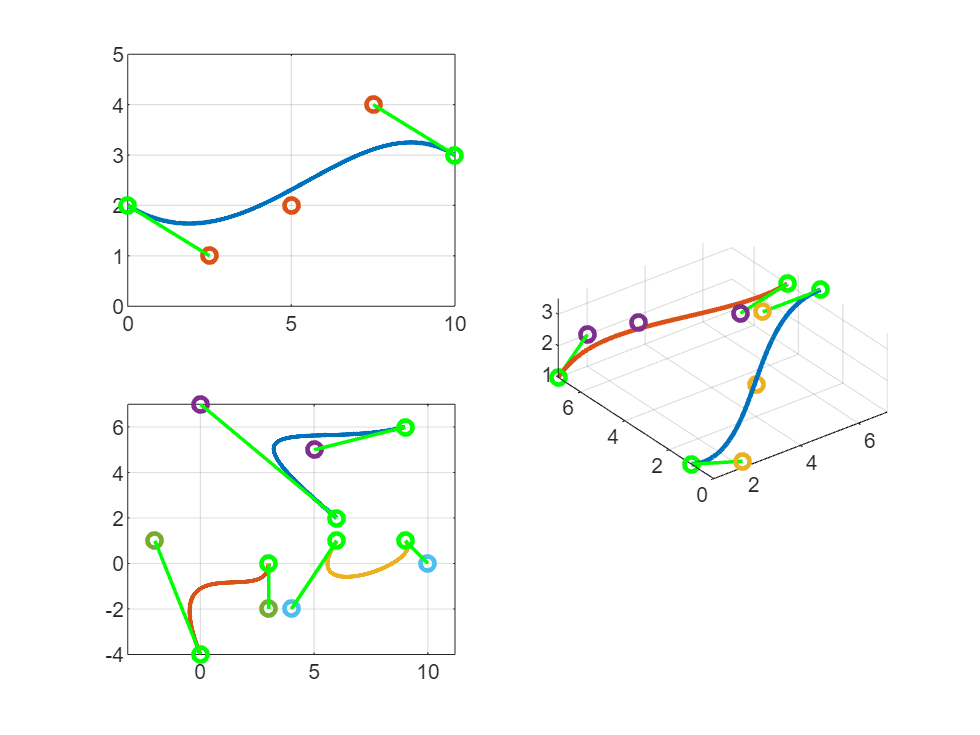

figure
subplot(2,2,1);
plot(t,xN,'LineWidth',2); hold on
tnodes = linspace(0,tf,length(x_N));
plot(tnodes,x_N,'o','LineWidth',2);
plot(tnodes(1),x_N(1),'o','LineWidth',2,'Color','g');
plot(tnodes(end),x_N(end),'o','LineWidth',2,'Color','g');
plot(tnodes(1:2),x_N(1:2),'LineWidth',1.5,'Color','g');
plot(tnodes(end-1:end),x_N(end-1:end),'LineWidth',1.5,'Color','g');
axis([0 10 0 5])
grid on
subplot(2,2,3)
plot(x1N(1,:),x1N(2,:),'LineWidth',2); hold on
plot(x2N(1,:),x2N(2,:),'LineWidth',2);
plot(x3N(1,:),x3N(2,:),'LineWidth',2);
plot(x1_N(1,:),x1_N(2,:),'o','LineWidth',2);
plot(x2_N(1,:),x2_N(2,:),'o','LineWidth',2);
plot(x3_N(1,:),x3_N(2,:),'o','LineWidth',2);
plot(x1_N(1,1),x1_N(2,1),'o','LineWidth',2,'Color','g');
plot(x1_N(1,end),x1_N(2,end),'o','LineWidth',2,'Color','g');
plot(x1_N(1,1:2),x1_N(2,1:2),'LineWidth',1.5,'Color','g');
plot(x1_N(1,end-1:end),x1_N(2,end-1:end),'LineWidth',1.5,'Color','g');
plot(x2_N(1,1),x2_N(2,1),'o','LineWidth',2,'Color','g');
plot(x2_N(1,end),x2_N(2,end),'o','LineWidth',2,'Color','g');
plot(x2_N(1,1:2),x2_N(2,1:2),'LineWidth',1.5,'Color','g');
plot(x2_N(1,end-1:end),x2_N(2,end-1:end),'LineWidth',1.5,'Color','g');
plot(x3_N(1,1),x3_N(2,1),'o','LineWidth',2,'Color','g');
plot(x3_N(1,end),x3_N(2,end),'o','LineWidth',2,'Color','g');
plot(x3_N(1,1:2),x3_N(2,1:2),'LineWidth',1.5,'Color','g');
plot(x3_N(1,end-1:end),x3_N(2,end-1:end),'LineWidth',1.5,'Color','g');
axis equal
grid on
subplot(2,2,[2,4])
plot3(p1N(1,:),p1N(2,:),p1N(3,:),'LineWidth',2); hold on
plot3(p2N(1,:),p2N(2,:),p2N(3,:),'LineWidth',2);
plot3(p1_N(1,:),p1_N(2,:),p1_N(3,:),'o','LineWidth',2);
plot3(p2_N(1,:),p2_N(2,:),p2_N(3,:),'o','LineWidth',2);
plot3(p1_N(1,1),p1_N(2,1),p1_N(3,1),'o','LineWidth',2,'Color','g');
plot3(p1_N(1,end),p1_N(2,end),p1_N(3,end),'o','LineWidth',2,'Color','g');
plot3(p1_N(1,1:2),p1_N(2,1:2),p1_N(3,1:2),'LineWidth',1.5,'Color','g');
plot3(p1_N(1,end-1:end),p1_N(2,end-1:end),p1_N(3,end-1:end),'LineWidth',1.5,'Color','g');
plot3(p2_N(1,1),p2_N(2,1),p2_N(3,1),'o','LineWidth',2,'Color','g');
plot3(p2_N(1,end),p2_N(2,end),p2_N(3,end),'o','LineWidth',2,'Color','g');
plot3(p2_N(1,1:2),p2_N(2,1:2),p2_N(3,1:2),'LineWidth',1.5,'Color','g');
plot3(p2_N(1,end-1:end),p2_N(2,end-1:end),p2_N(3,end-1:end),'LineWidth',1.5,'Color','g');
axis equal
grid on

## Convex Hull Property

A Bernstein polynomial is completely contained in the convex hull of its Bernstein coefficients. Given a 1D Bernstein polynomial $x_N(t) : [0,t_f] \to \mathbb{R}$with Bernstein coefficients $\bar{x}_{j,N} \in \mathbb{R}, \quad j=0,\ldots,N$, the convex hull property implies that the following inequality holds:


$$\min_j \bar{x}_{j,N} \leq x_N(t) \leq \max_j \bar{x}_{j,N}$$


for all $t \in [0,t_f]$. The following figures provide a depiction of this property. 

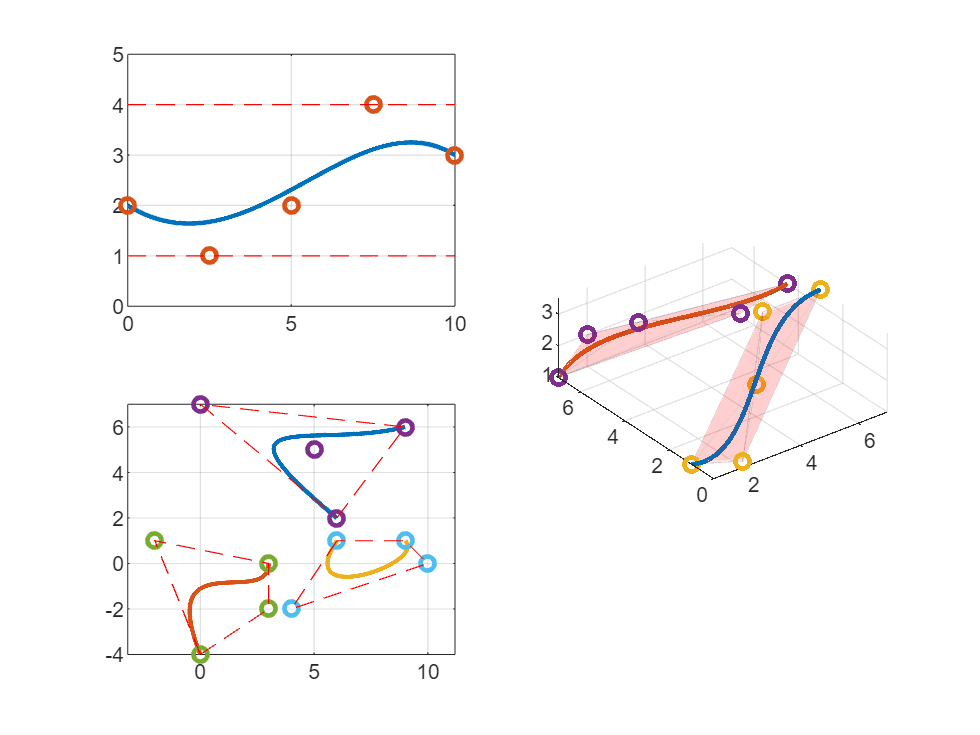

figure
subplot(2,2,1);
plot(t,xN,'LineWidth',2); hold on
plot(linspace(0,tf,length(x_N)),x_N,'o','LineWidth',2);
plot(linspace(0,tf,length(x_N)),ones(length(x_N))*max(x_N),'--','LineWidth',0.5,'Color','r');
plot(linspace(0,tf,length(x_N)),ones(length(x_N))*min(x_N),'--','LineWidth',0.5,'Color','r');
axis([0 10 0 5])
grid on
subplot(2,2,3)
plot(x1N(1,:),x1N(2,:),'LineWidth',2); hold on
plot(x2N(1,:),x2N(2,:),'LineWidth',2);
plot(x3N(1,:),x3N(2,:),'LineWidth',2);
plot(x1_N(1,:),x1_N(2,:),'o','LineWidth',2);
plot(x2_N(1,:),x2_N(2,:),'o','LineWidth',2);
plot(x3_N(1,:),x3_N(2,:),'o','LineWidth',2);
[k,av] = convhull(x1_N');
plot(x1_N(1,k),x1_N(2,k),'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(x2_N');
plot(x2_N(1,k),x2_N(2,k),'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(x3_N');
plot(x3_N(1,k),x3_N(2,k),'--','LineWidth',0.5,'Color','r');
axis equal
grid on
subplot(2,2,[2,4])
plot3(p1N(1,:),p1N(2,:),p1N(3,:),'LineWidth',2); hold on
plot3(p2N(1,:),p2N(2,:),p2N(3,:),'LineWidth',2);
plot3(p1_N(1,:),p1_N(2,:),p1_N(3,:),'o','LineWidth',2);
plot3(p2_N(1,:),p2_N(2,:),p2_N(3,:),'o','LineWidth',2);
[k,av] = convhull(p1_N');
trisurf(k,p1_N(1,:),p1_N(2,:),p1_N(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
[k,av] = convhull(p2_N');
trisurf(k,p2_N(1,:),p2_N(2,:),p2_N(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
axis equal
grid on

## Degree Elevation

A Bernstein polynomial ${x}_N(t)$ of degree $N$ with Bernstein coefficients $\bar{x}_{j,N}$, $j = 0,\ldots,N$, can be expressed as a Bernstein polynomial ${x}_M(t)$ of degree $M$, $M > N$, with Bernstein coefficients given by


$$\bar{x}_{k,M} = \sum_{j=\max{(0,k+M-N)}}^{\min{(N,k)}} \frac{\Big( \begin{array}{c} {M-N} \\ {k-j} \end{array} \Big) \Big( \begin{array}{c} {N} \\ {j} \end{array} \Big) }{\Big( \begin{array}{c} {M} \\ {k} \end{array} \Big)}\bar{x}_{j,N}, $$


with $k = 0, \dots, M$. The above equation can be rewritten in matrix form as


$$\bar{x}_{M} =    
	\bar{x}_{N}
	\mathbf{E}_N^{M},$$


where $\bar{x}_N = [\bar{x}_{0,N} , \ldots , \bar{x}_{N,N}]$ and $\bar{x}_M = [\bar{x}_{0,M} , \ldots , \bar{x}_{M,M}]$ are the vectors of Bernstein coefficients, and $\mathbf{E}_N^{M} = \{e_{j,k}\}  \in \mathbb{R}^{N+1 \times M+1}$ is the matrix of degree elevation from order $N$ to order $M$ with


$$e_{i,i+j} = \frac{\Big( \begin{array}{c} {M-N} \\ {j} \end{array} \Big) \Big( \begin{array}{c}  {N} \\ {i} \end{array} \Big)}{\Big( \begin{array}{c} {M} \\ {i+j} \end{array} \Big) },$$


$i=0,\ldots,N$ and $j=0,\ldots,M-N$.

In BeBOT, the function "DegElevMatrix(N,M)" generates the degree elevation matrix given above. The following figures illustrate examples where the 1D, 2D and 3D Bernstein polynomials defined earlier are degree elevated.

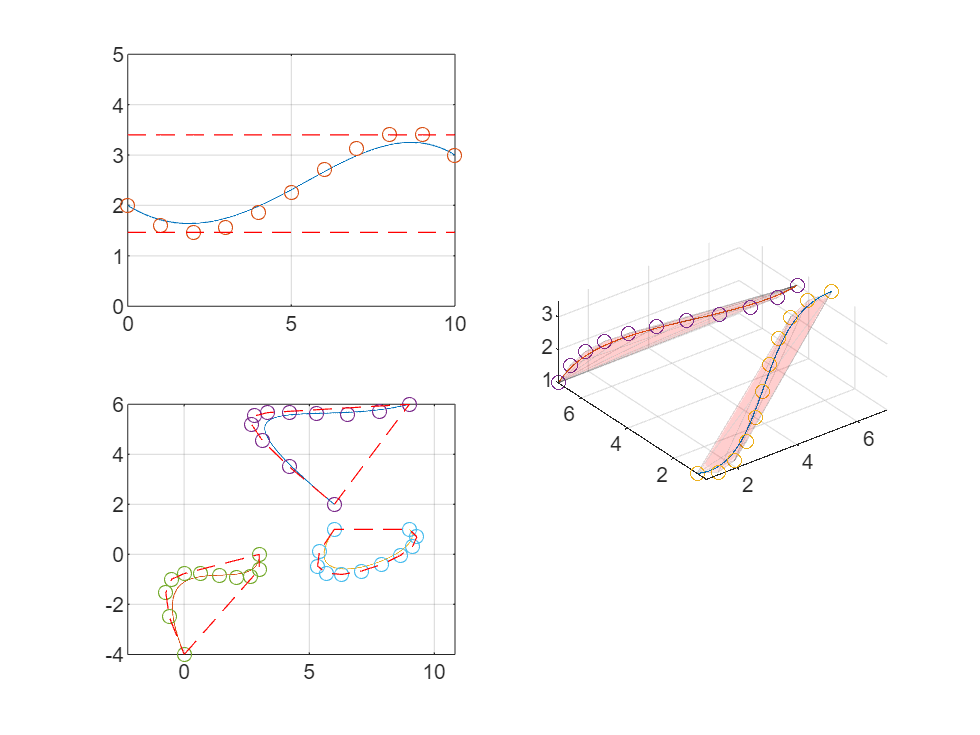

M = 10; % Elevate to Mth order


% Degree elevate the coefficients of the 1D Bernstein polynomial
x_N_elev = x_N*DegElevMatrix(length(x_N)-1,M);

% Degree elevate the coefficients of the 2D Bernstein polynomials
x1_N_elev = x1_N*DegElevMatrix(length(x1_N)-1,M);
x2_N_elev = x2_N*DegElevMatrix(length(x2_N)-1,M);
x3_N_elev = x3_N*DegElevMatrix(length(x3_N)-1,M);

% Degree elevate the coefficients of the 3D Bernstein polynomials
p1_N_elev = p1_N*DegElevMatrix(length(p1_N)-1,M);
p2_N_elev = p2_N*DegElevMatrix(length(p2_N)-1,M);

% Plot
figure
subplot(2,2,1);
plot(t,xN); hold on
plot(linspace(0,tf,length(x_N_elev)),x_N_elev,'o');
plot(linspace(0,tf,length(x_N_elev)),ones(length(x_N_elev))*max(x_N_elev),'--','LineWidth',0.5,'Color','r');
plot(linspace(0,tf,length(x_N_elev)),ones(length(x_N_elev))*min(x_N_elev),'--','LineWidth',0.5,'Color','r');
axis([0 10 0 5])
grid on
subplot(2,2,3)
plot(x1N(1,:),x1N(2,:)); hold on
plot(x2N(1,:),x2N(2,:));
plot(x3N(1,:),x3N(2,:));
plot(x1_N_elev(1,:),x1_N_elev(2,:),'o');
plot(x2_N_elev(1,:),x2_N_elev(2,:),'o');
plot(x3_N_elev(1,:),x3_N_elev(2,:),'o');
[k,av] = convhull(x1_N_elev');
plot(x1_N_elev(1,k),x1_N_elev(2,k),'--','Color','r');
[k,av] = convhull(x2_N_elev');
plot(x2_N_elev(1,k),x2_N_elev(2,k),'--','Color','r');
[k,av] = convhull(x3_N_elev');
plot(x3_N_elev(1,k),x3_N_elev(2,k),'--','Color','r');
axis equal
grid on
subplot(2,2,[2,4])
plot3(p1N(1,:),p1N(2,:),p1N(3,:)); hold on
plot3(p2N(1,:),p2N(2,:),p2N(3,:));
plot3(p1_N_elev(1,:),p1_N_elev(2,:),p1_N_elev(3,:),'o');
plot3(p2_N_elev(1,:),p2_N_elev(2,:),p2_N_elev(3,:),'o');
[k,av] = convhull(p1_N_elev');
trisurf(k,p1_N_elev(1,:),p1_N_elev(2,:),p1_N_elev(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
[k,av] = convhull(p2_N_elev');
trisurf(k,p2_N_elev(1,:),p2_N_elev(2,:),p2_N_elev(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
axis equal
grid on

It can be noted that the Bernstein coefficients of a degree elevated Bernstein polynomial converge to the polynomial itself. Mathematically, we have


$$\max_j \left\Vert\bar{x}_{j,M} - {x}_M\left(\frac{j}{M}t_f\right)\right\Vert \leq \frac{C_d}{M}$$


where $C_d$ is a positive constant independent of $M$. The equation above implies that by applying degree elevation and using the convex hull property, one can easily compute a convex shape that is less conservative than the original convex hull and that still contains the Bernstein polynomial.

## de Casteljau Algorithm

The de Casteljau algorithm is an efficient and numerically stable recursive method to evaluate a Bernstein polynomial at any given point. The algorithm is also used to split a Bernstein polynomial into two independent ones.

Given an $N$th order Bernstein polynomial ${x}_N: [0,t_f] \to \mathbb{R}^n$, and a scalar $\lambda \in [0,1]$, the Bernstein polynomial at $t_{\text{div}} = \lambda t_f$ can be computed using the following recursive relation:


$${\bar{x}}_{i,N}^{[0]} = {\bar{x}}_{i,N}\, , \quad i = 0,\ldots,N \, ,$$



$${\bar{x}}_{i,N}^{[j]} = {\bar{x}}_{i,N}^{[j-1]} (1-\lambda) + {\bar{x}}_{i+1,N}^{[j-1]} \lambda  \, , $$


with $i = 0,\ldots,N-j \, ,$ and $j = 1,\ldots,N$. Then, the Bernstein polynomial evaluated at $t_{\text{div}}$ is given by


$${x}_N(t_{\text{div}}) = {\bar{x}}_{0,N}^{[N]} \, .$$


Moreover, the Bernstein polynomial can be subdivided at $t_{\text{div}}$ into two $N$th order Bernstein polynomials with Bernstein coefficients


$${\bar{x}}_{0,N}^{[0]},{\bar{x}}_{0,N}^{[1]},\ldots,{\bar{x}}_{0,N}^{[N]} \, , \quad \text{and} \quad
	{\bar{x}}_{0,N}^{[N]},{\bar{x}}_{1,N}^{[N-1]},\ldots,{\bar{x}}_{N,N}^{[0]} \, .$$


The following figures depict Bernstein polynomials (with Bernstein coefficients defined earlier) that are subdivided into two 5th order Bernstein polynomials at $$\lambda = 0.5$$ (i.e. they are split at $$t_f/2$$).

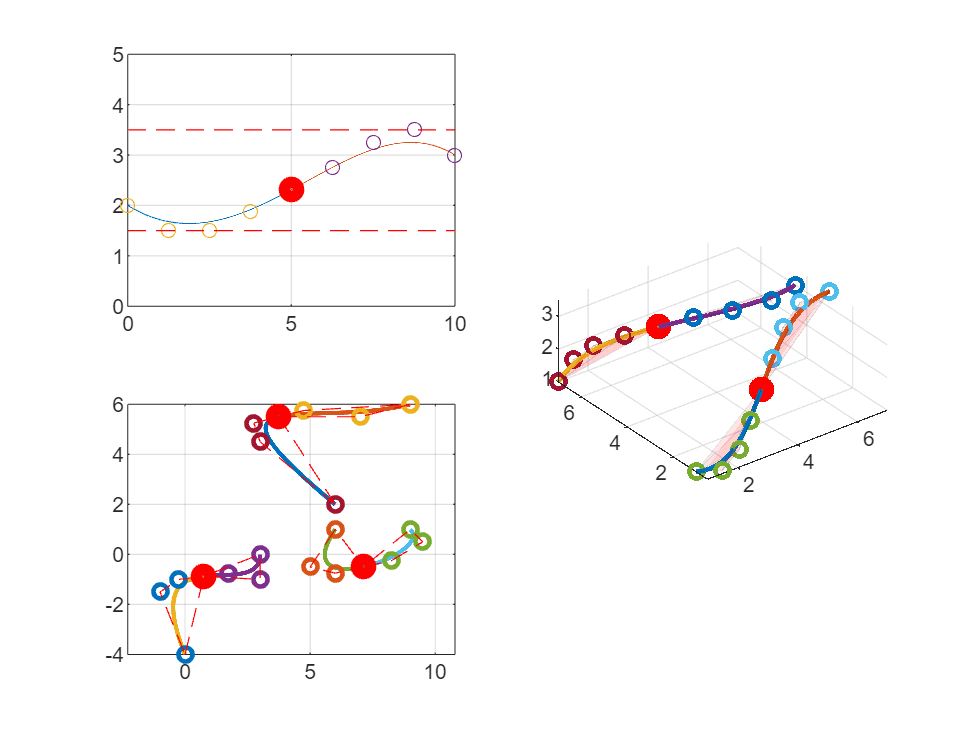

lambda = 0.5; % Value at which we subdivide (lambda \in [0,1])


% Subdivide the 1D Bernstein polynomials at lambda 
[Cpout Pos] = deCasteljau(x_N,lambda); 
% Pos is the value of xN at lambda*tf (or xN(lambda*tf))
x_NA = Cpout(:, 1:length(x_N(1,:)));
x_NB = Cpout(:, length(x_N(1,:)):end);
% x_NA and x_NB are the coefficients of the two Bernstein polynomials
xNA = BernsteinPoly(x_NA,t);
xNB = BernsteinPoly(x_NB,t);


% Plot
figure
subplot(2,2,1);
tA = linspace(0,lambda,length(xNA))*tf;
tB = linspace(lambda,1,length(xNA))*tf;
plot(tA,xNA); hold on
plot(tB,xNB);
plot(linspace(0,lambda*tf,length(x_NA)),x_NA,'o');
plot(linspace(lambda*tf,tf,length(x_NB)),x_NB,'o');
plot(lambda*tf,Pos,'o','LineWidth',5,'Color','r');
plot(linspace(0,tf,length(x_N)),ones(length(x_N))*max(max(x_NA),max(x_NB)),'--','LineWidth',0.5,'Color','r');
plot(linspace(0,tf,length(x_N)),ones(length(x_N))*min(min(x_NA),min(x_NB)),'--','LineWidth',0.5,'Color','r');
axis([0 10 0 5])
grid on

% Subdivide the 2D Bernstein polynomials at lambda 
[Cpout Pos1] = deCasteljau(x1_N,lambda);
x1_NA = Cpout(:, 1:length(x1_N(1,:)));
x1_NB = Cpout(:, length(x1_N(1,:)):end);
x1NA = BernsteinPoly(x1_NA,t);
x1NB = BernsteinPoly(x1_NB,t);
[Cpout Pos2] = deCasteljau(x2_N,lambda);
x2_NA = Cpout(:, 1:length(x2_N(1,:)));
x2_NB = Cpout(:, length(x2_N(1,:)):end);
x2NA = BernsteinPoly(x2_NA,t);
x2NB = BernsteinPoly(x2_NB,t);
[Cpout Pos3] = deCasteljau(x3_N,lambda);
x3_NA = Cpout(:, 1:length(x3_N(1,:)));
x3_NB = Cpout(:, length(x3_N(1,:)):end);
x3NA = BernsteinPoly(x3_NA,t);
x3NB = BernsteinPoly(x3_NB,t);

% Plot
subplot(2,2,3)
plot(x1NA(1,:),x1NA(2,:),'LineWidth',2); hold on
plot(x1NB(1,:),x1NB(2,:),'LineWidth',2); 
plot(x2NA(1,:),x2NA(2,:),'LineWidth',2);
plot(x2NB(1,:),x2NB(2,:),'LineWidth',2);
plot(x3NA(1,:),x3NA(2,:),'LineWidth',2);
plot(x3NB(1,:),x3NB(2,:),'LineWidth',2);
plot(x1_NA(1,:),x1_NA(2,:),'o','LineWidth',2);
plot(x2_NA(1,:),x2_NA(2,:),'o','LineWidth',2);
plot(x3_NA(1,:),x3_NA(2,:),'o','LineWidth',2);
plot(x1_NB(1,:),x1_NB(2,:),'o','LineWidth',2);
plot(x2_NB(1,:),x2_NB(2,:),'o','LineWidth',2);
plot(x3_NB(1,:),x3_NB(2,:),'o','LineWidth',2);
plot(Pos1(1),Pos1(2),'o','LineWidth',5,'Color','r');
plot(Pos2(1),Pos2(2),'o','LineWidth',5,'Color','r');
plot(Pos3(1),Pos3(2),'o','LineWidth',5,'Color','r');
[k,av] = convhull(x1_NA');
plot(x1_NA(1,k),x1_NA(2,k),'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(x1_NB');
plot(x1_NB(1,k),x1_NB(2,k),'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(x2_NA');
plot(x2_NA(1,k),x2_NA(2,k),'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(x2_NB');
plot(x2_NB(1,k),x2_NB(2,k),'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(x3_NA');
plot(x3_NA(1,k),x3_NA(2,k),'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(x3_NB');
plot(x3_NB(1,k),x3_NB(2,k),'--','LineWidth',0.5,'Color','r');
%set(gca,'fontsize', 40);
axis equal
grid on

% Subdivide the 3D Bernstein polynomials at lambda
[Cpout Pos1] = deCasteljau(p1_N,lambda);
p1_NA = Cpout(:, 1:length(p1_N(1,:)));
p1_NB = Cpout(:, length(p1_N(1,:)):end);
p1NA = BernsteinPoly(p1_NA,t);
p1NB = BernsteinPoly(p1_NB,t);
[Cpout Pos2] = deCasteljau(p2_N,lambda);
p2_NA = Cpout(:, 1:length(p2_N(1,:)));
p2_NB = Cpout(:, length(p2_N(1,:)):end);
p2NA = BernsteinPoly(p2_NA,t);
p2NB = BernsteinPoly(p2_NB,t);
subplot(2,2,[2,4])
plot3(p1NA(1,:),p1NA(2,:),p1NA(3,:),'LineWidth',2); hold on
plot3(p1NB(1,:),p1NB(2,:),p1NB(3,:),'LineWidth',2);
plot3(p2NA(1,:),p2NA(2,:),p2NA(3,:),'LineWidth',2);
plot3(p2NB(1,:),p2NB(2,:),p2NB(3,:),'LineWidth',2);
plot3(p1_NA(1,:),p1_NA(2,:),p1_NA(3,:),'o','LineWidth',2);
plot3(p1_NB(1,:),p1_NB(2,:),p1_NB(3,:),'o','LineWidth',2);
plot3(p2_NA(1,:),p2_NA(2,:),p2_NA(3,:),'o','LineWidth',2);
plot3(p2_NB(1,:),p2_NB(2,:),p2_NB(3,:),'o','LineWidth',2);
plot3(Pos1(1),Pos1(2),Pos1(3),'o','LineWidth',5,'Color','r');
plot3(Pos2(1),Pos2(2),Pos2(3),'o','LineWidth',5,'Color','r');
[k,av] = convhull(p1_NA');
trisurf(k,p1_NA(1,:),p1_NA(2,:),p1_NA(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
[k,av] = convhull(p1_NB');
trisurf(k,p1_NB(1,:),p1_NB(2,:),p1_NB(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
[k,av] = convhull(p2_NA');
trisurf(k,p2_NA(1,:),p2_NA(2,:),p2_NA(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
[k,av] = convhull(p2_NB');
trisurf(k,p2_NB(1,:),p2_NB(2,:),p2_NB(3,:),'FaceColor','r','FaceAlpha',.1,'EdgeAlpha',.1)
axis equal
grid on

Notice that by employing the de Casteljau algorithm, smaller convex hulls containing the Bernstein polynomials are obtained. 

## Minimum Distance Algorithm

By exploiting the convex-hull property, the end point values property, and the de Casteljau algorithm, in combination with the Gilbert-Johnson-Keerthi (GJK) distance algorithm, one can implement computationally efficient algorithms to evaluate the minimum distance between two Bernstein polynomials, ${f}_N(t)$ and ${g}_N(t)$, namely


$$ \min_{t_a,t_b\in [0,t_f]} ||{f}_N(t_a)-{g}_N(t_b)||  $$



$$ \text{argmin}_{t_a,t_b\in [0,t_f]} ||{f}_N(t_a)-{g}_N(t_b)||$$


In few words, the GJK algorithm, widely used in computer graphics and video games to compute the minimum distance between convex shapes, can be used to compute the distance between two convex hulls containing Bernstein polynomials. The de Casteljau algorithm can be used to split these convex hulls in smaller objects. These two algorithms can be repeated iteratively until the points of minimum distance are the end points of the polynomials' subdivisions. The same procedure can be also used to compute the extrema of a 1D Bernstein polynomials, or the distance between a Bernstein polynomial and a convex shape.  

BeBOT offers functions to compute the minimum distance between two 2D or 3D Bernstein polynomials, namely "***MinDistBernstein2Bernstein.m***", the minimum distance between a 2D or 3D Bernstein polynomials and a convex shape, namely "***MinDistBernstein2Polygon.m***", and the extrema of a 1D Bernstein polynomial, namely "***MaximumBernstein.m***" and "***MinimumBernstein.m***".

The figures below are obtained using these functions:

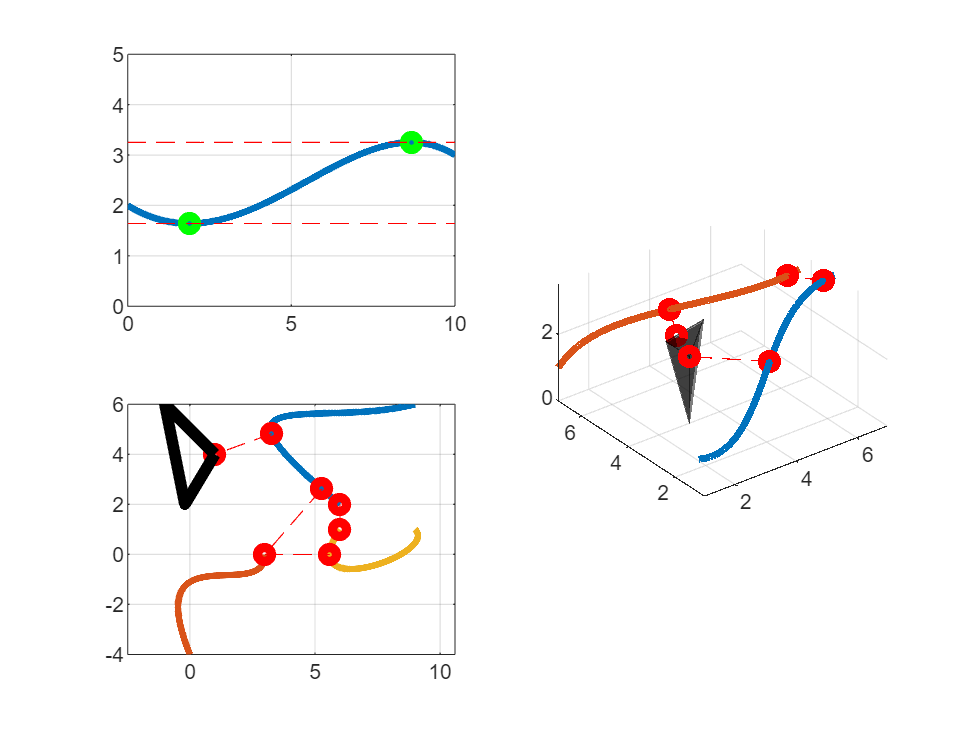

% Compute max and min of a 1D Bernstein polynomial
[max, tmax] = MaximumBernstein(x_N);
[~, pmax] = deCasteljau(x_N,tmax);
[min, tmin] = MinimumBernstein(x_N);
[~, pmin] = deCasteljau(x_N,tmin);


% Plot
figure
subplot(2,2,1);
plot(t,xN,'LineWidth',3); hold on
tnodes = linspace(0,tf,length(x_N));
plot(tmax*tf,max,'o','LineWidth',4,'Color','g');
plot(linspace(0,10,tf),max*ones(10,1),'--','LineWidth',0.5,'Color','r');
plot(tmin*tf,min,'o','LineWidth',4,'Color','g');
plot(linspace(0,10,tf),min*ones(10,1),'--','LineWidth',0.5,'Color','r');
axis([0 10 0 5])
grid on

% Compute distance between 2D Bernstein polynomials
% and between 2D Bernstein polynomials and convex shapes
[dist, t1, t2] = MinDistBernstein2Bernstein(x1_N, x2_N);
[~,x12col1] = deCasteljau(x1_N,t1);
[~,x12col2] = deCasteljau(x2_N,t2);
[dist, t1, t3] = MinDistBernstein2Bernstein(x1_N, x3_N);
[~,x13col1] = deCasteljau(x1_N,t1);
[~,x13col3] = deCasteljau(x3_N,t3);
[dist, t2, t3] = MinDistBernstein2Bernstein(x2_N, x3_N);
[~,x23col2] = deCasteljau(x2_N,t2);
[~,x23col3] = deCasteljau(x3_N,t3);
shape = [1 -1  -0.2; 4 6 2];
[dist, t, pt] = MinDistBernstein2Polygon(x1_N, shape);
[~,x1shapecol1] = deCasteljau(x1_N,t);


% Plot
subplot(2,2,3)
plot(x1N(1,:),x1N(2,:),'LineWidth',3); hold on
plot(x2N(1,:),x2N(2,:),'LineWidth',3);
plot(x3N(1,:),x3N(2,:),'LineWidth',3);
plot(x12col1(1),x12col1(2),'o','LineWidth',4,'Color','r');
plot(x12col2(1),x12col2(2),'o','LineWidth',4,'Color','r');
plot([x12col1(1) x12col2(1)],[x12col1(2) x12col2(2)],'--','LineWidth',0.5,'Color','r');
plot(x13col1(1),x13col1(2),'o','LineWidth',4,'Color','r');
plot(x13col3(1),x13col3(2),'o','LineWidth',4,'Color','r');
plot([x13col1(1) x13col3(1)],[x13col1(2) x13col3(2)],'--','LineWidth',0.5,'Color','r');
plot(x23col2(1),x23col2(2),'o','LineWidth',4,'Color','r');
plot(x23col3(1),x23col3(2),'o','LineWidth',4,'Color','r');
plot([x23col2(1) x23col3(1)],[x23col2(2) x23col3(2)],'--','LineWidth',0.5,'Color','r');
plot(x1shapecol1(1),x1shapecol1(2),'o','LineWidth',4,'Color','r');
plot(pt(1),pt(2),'o','LineWidth',4,'Color','r');
plot([x1shapecol1(1) pt(1)],[x1shapecol1(2) pt(2)],'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(shape');
plot(shape(1,k),shape(2,k),'-','LineWidth',5,'Color','k');
%set(gca,'fontsize', 40);
axis equal
grid on
%set(gca, 'Units', 'Normalized', 'OuterPosition', [0.02, 0.02, 0.45, 0.45]);


% Compute distance between 3D Bernstein polynomials
[dist, t1, t2] = MinDistBernstein2Bernstein(p1_N, p2_N);
[~,pcol1] = deCasteljau(p1_N,t1);
[~,pcol2] = deCasteljau(p2_N,t2);
shape = [3 3 3 5; 4 4 5 6; 0 2 2 1.5];
[dist, t, pt1] = MinDistBernstein2Polygon(p1_N, shape);
[~,pcol1shape] = deCasteljau(p1_N,t);
[dist, t, pt2] = MinDistBernstein2Polygon(p2_N, shape);
[~,pcol2shape] = deCasteljau(p2_N,t);


% Plot
subplot(2,2,[2,4])
plot3(p1N(1,:),p1N(2,:),p1N(3,:),'LineWidth',3); hold on
plot3(p2N(1,:),p2N(2,:),p2N(3,:),'LineWidth',3);
plot3(pcol1(1),pcol1(2),pcol1(3),'o','LineWidth',4,'Color','r');
plot3(pcol2(1),pcol2(2),pcol2(3),'o','LineWidth',4,'Color','r');
plot3([pcol1(1) pcol2(1)],[pcol1(2) pcol2(2)],[pcol1(3) pcol2(3)],'--','LineWidth',0.5,'Color','r');
%set(gca,'fontsize', 40);
axis equal
grid on
%set(gca, 'Units', 'Normalized', 'OuterPosition', [0.35, 0.15, 0.8, 0.8]);
plot3(pcol1shape(1),pcol1shape(2),pcol1shape(3),'o','LineWidth',4,'Color','r');
plot3(pcol2shape(1),pcol2shape(2),pcol2shape(3),'o','LineWidth',4,'Color','r');
plot3(pt1(1),pt1(2),pt1(3),'o','LineWidth',4,'Color','r');
plot3(pt2(1),pt2(2),pt2(3),'o','LineWidth',4,'Color','r');
plot3([pcol1shape(1) pt1(1)],[pcol1shape(2) pt1(2)],[pcol1shape(3) pt1(3)],'--','LineWidth',0.5,'Color','r');
plot3([pcol2shape(1) pt2(1)],[pcol2shape(2) pt2(2)],[pcol2shape(3) pt2(3)],'--','LineWidth',0.5,'Color','r');
[k,av] = convhull(shape');
%set(gca,'fontsize', 40);
trisurf(k,shape(1,:),shape(2,:),shape(3,:),'FaceColor','k','FaceAlpha',.5,'EdgeAlpha',.5)

## Check Collision

BeBOT can be used to check whether the minimum distance between two Bernstein polynomials, or between a Bernstein polynomials and a convex shape, is greater than a minimun specified distance. The check collision algorithms returns a 0 (collision occurs) or 1 (collision does not occur) and is more computationally efficient than the minimum distance algorithm. Here is an example

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Check collision algorithm
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
collision = CollCheckBernstein2Bernstein(p1_N, p2_N, 1.6)

collision = logical
   1


collision = CollCheckBernstein2Bernstein(p1_N, p2_N, 1.5)

collision = logical
   0


collision = CollCheckBernstein2Polygon(p1_N, shape, 2.4)

collision = logical
   1


collision = CollCheckBernstein2Polygon(p1_N, shape, 2.3)

collision = logical
   0


## Arithmetic Operations

The sum (difference) of two polynomials of the same order can be performed by simply adding (subtracting) their Bernstein coefficients. Let $f_M(t)$ and $g_N(t)$ be two 1-dimensional Bernstein polynomials of degree $M$ and $N$, respectively, with coefficients $\bar{f}_{M}=[\bar{f}_{0,M}, \dots, \bar{f}_{M,M}]$ and $\bar{g}_{N}=[\bar{g}_{0,N}, \dots, \bar{g}_{N,N}]$. The product $y_{M+N}(t)=f_M(t)g_N(t)$ is a Bernstein polynomial of degree $(M+N)$ with coefficients $\bar{y}_{M+N}=[\bar{y}_{0,M+N},\ldots,\bar{y}_{M+N,M+N}]$, given by


$$\bar{y}_{k,M+N} = \sum_{j=\max(0,k-N)}^{\min(M,k)} \frac{\Big( \begin{array}{c} {M} \\ {j} \end{array} \Big) \Big( \begin{array}{c} {N} \\ {k-j} \end{array} \Big) }{\Big( \begin{array}{c} {M+N} \\ {k} \end{array} \Big) } \bar{f}_{j, M} \bar{g}_{k-j, N}.$$


With BeBOT, the Bernstein coefficients of the product between two Bernstein polynomials are easily computed as follows:

% Compute Bernstein coefficients of product
f_M = [2 4 6 9 4];
g_N = [3 2 1 1 3 8 2];
y_MpN = BernsteinProduct(f_M,g_N);

The ratio between two 1D Bernstein polynomials, $f_N(t)$ and $g_N(t)$, with Bernstein coefficients $\bar{f}_{0,N}, \dots, \bar{f}_{N,N}$ and $\bar{g}_{0,N}, \dots, \bar{g}_{N,N}$, i.e., $r_N(t)=f_N(t)/g_N(t)$, can be expressed as a $N$th order *rational* Bernstein polynomial defined as


$$	r_N(t) =
	\frac{\sum_{i=0}^n{\bar{r}_{i,N} {w}_{i,n} b_{i,N} (t)}}
	{\sum_{i=0}^n{{w}_{i,N} b_{i,N} (t)}}, \quad
	t \in [0, t_f],
$$


with coefficients and weights $\bar{r}_{i,N} = \frac{{\bar{f}}_{i,N}}{{\bar{g}}_{i,N}} \, , \quad {w}_{i,N} = {\bar{f}}_{i,N}.$

The end point values, convex hull, and degree elevation properties apply also to rational Bernstein polynomials. The de Casteljau and minimum distance algorithms can be easily extended to *rational* Bernstein polynomials.

# Bernstein Polynomials as Vehicles' Trajectories

In what follows we present the use of Bernstein polynomials as a tool to represent vehicle trajectories. 

## 2D Trajectories

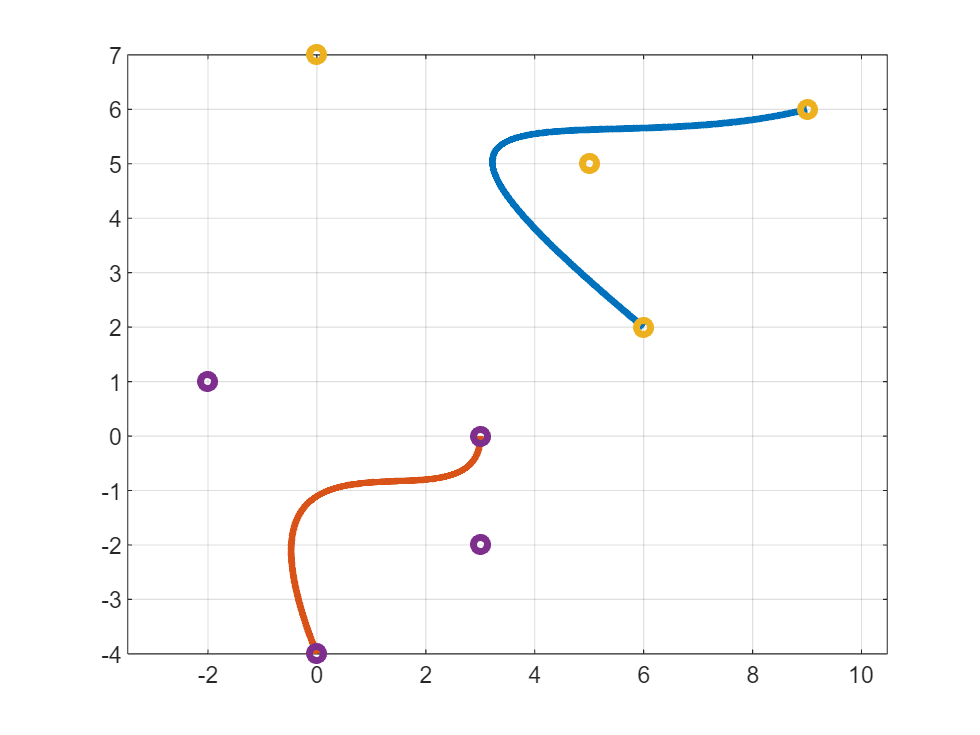

clear all

tf = 10;
t = linspace(0,tf,1000);

% 2D Bernstein Polynomials
x1_N = [6 0 5 9; 2 7 5 6];
x2_N = [0 -2 3 3; -4 1 -2 0];
x1N = BernsteinPoly(x1_N,t);
x2N = BernsteinPoly(x2_N,t);

% Plot
figure
plot(x1N(1,:),x1N(2,:),'LineWidth',3); hold on
plot(x2N(1,:),x2N(2,:),'LineWidth',3);
plot(x1_N(1,:),x1_N(2,:),'o','LineWidth',3);
plot(x2_N(1,:),x2_N(2,:),'o','LineWidth',3);
axis equal
grid on

Given the 2D trajectories above, the speed (square) of the vehicles can be computed as follows

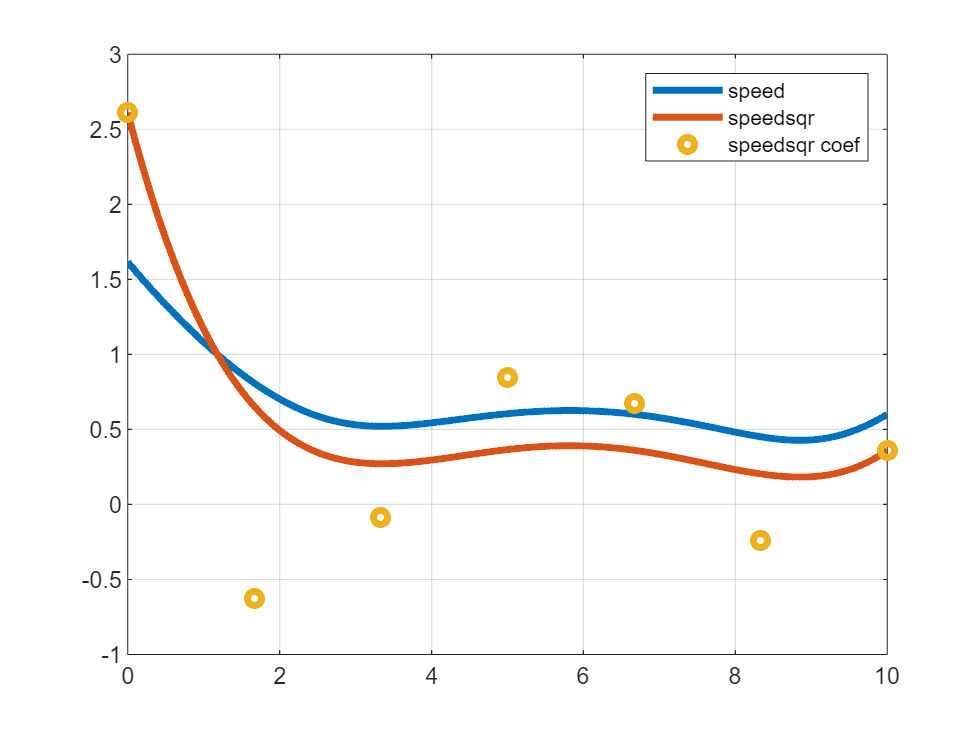

%% Speed square
[~,N] = size(x2_N);
N = N - 1;
[tnodes,w,Dm] = BeBOT(N,tf);
x2_Ndot = x2_N*Dm;
speedsqr_2N = BernsteinProduct(x2_Ndot(1,:),x2_Ndot(1,:))+BernsteinProduct(x2_Ndot(2,:),x2_Ndot(2,:));
speedsqr2N = BernsteinPoly(speedsqr_2N,t);
speed2N = sqrt(speedsqr2N);

% Plot
figure
plot(t,speed2N,'LineWidth',3); hold on
plot(t,speedsqr2N,'LineWidth',3);
plot(linspace(0,tf,2*N+1),speedsqr_2N,'o','LineWidth',3);
legend('speed','speedsqr','speedsqr coef')
grid on

The angular rates can be computed as follows

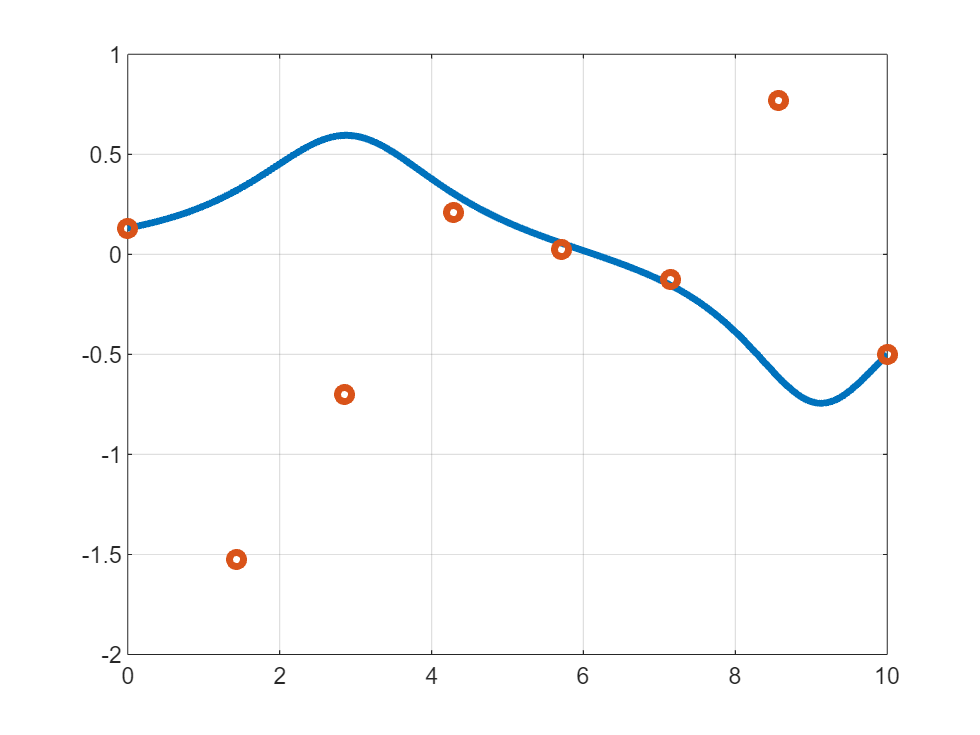

%% Psidot
x2_Nddot = x2_Ndot*Dm;
psidot_num = (BernsteinProduct(x2_Nddot(1,:),x2_Ndot(2,:))-BernsteinProduct(x2_Nddot(2,:),x2_Ndot(1,:)));
psidot_num = psidot_num*DegElevMatrix(length(psidot_num)-1,length(psidot_num));
psidot_den = speedsqr_2N*DegElevMatrix(length(speedsqr_2N)-1,length(speedsqr_2N));
psidot_coeff = psidot_num./(psidot_den);
psidot_weights = (psidot_den); 
psidot = BernsteinPoly(psidot_num,t)./BernsteinPoly(psidot_den,t);

% Plot
figure
plot(t,psidot,'LineWidth',3); hold on
plot(linspace(0,tf,length(psidot_coeff)),psidot_coeff,'o','LineWidth',3);
grid on

These can be degree elevated

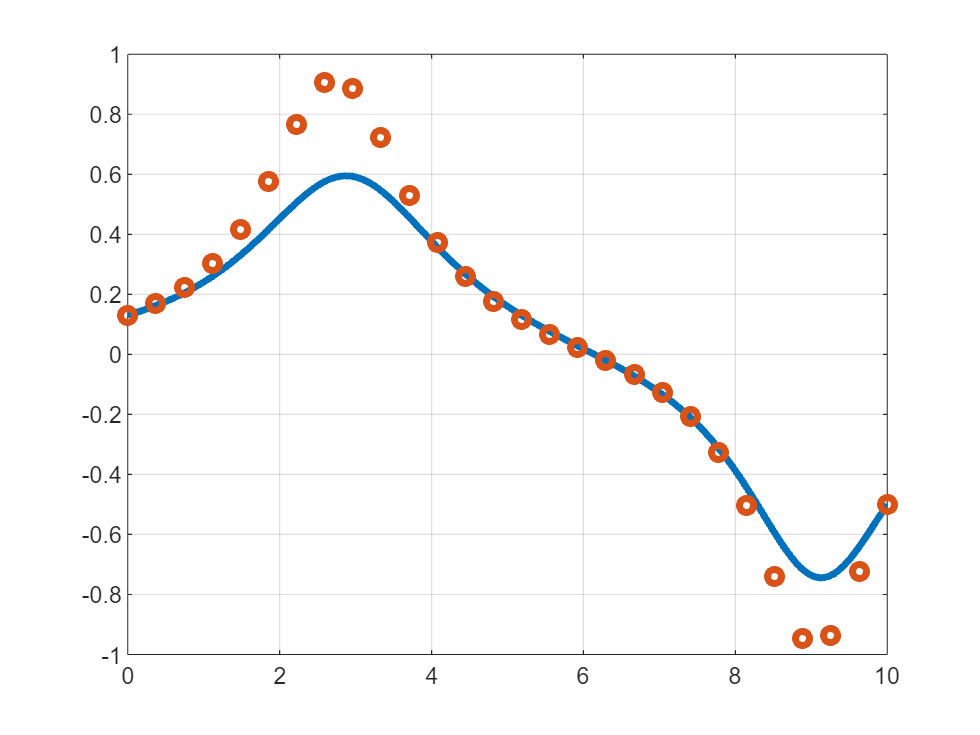

% Degree elevate
[~,N] = size(psidot_num);
N = N - 1;
psidot_num = psidot_num*DegElevMatrix(N,N+20);
psidot_den = psidot_den*DegElevMatrix(N,N+20);
psidot_coeff = psidot_num./psidot_den;
psidot_weights = psidot_den; 
psidot = BernsteinPoly(psidot_num,t)./BernsteinPoly(psidot_den,t);

% Plot
figure
plot(t,psidot,'LineWidth',3); hold on
[~,M] = size(psidot_coeff);
plot(linspace(0,tf,M),psidot_coeff,'o','LineWidth',3);
grid on

or subdivided

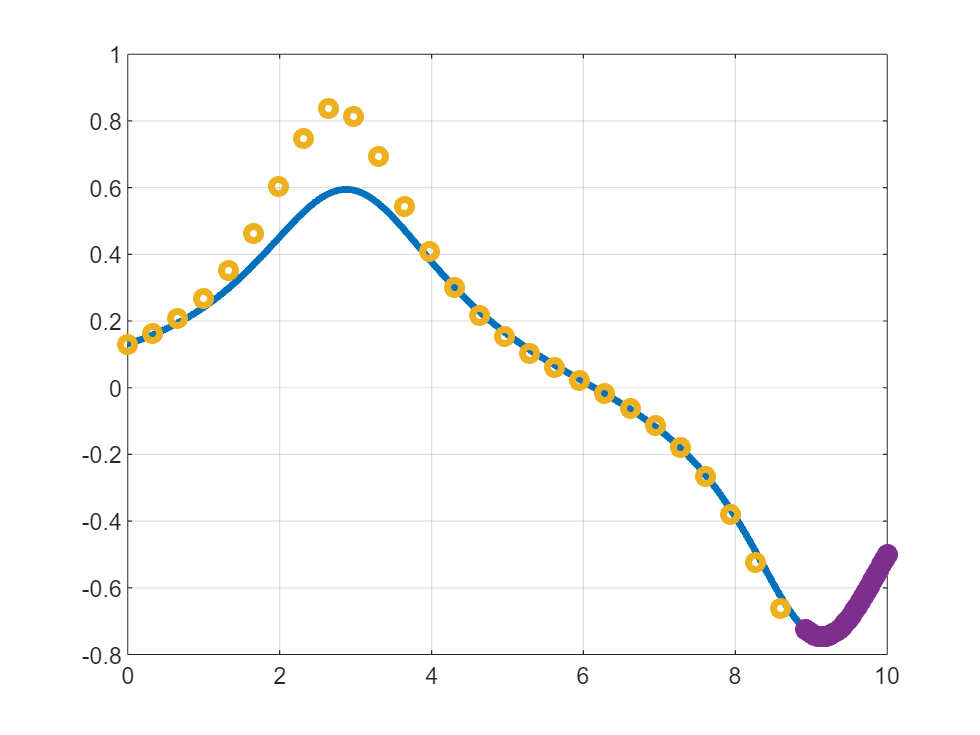

% Subdivide at min 
[minv,iminv] = min(psidot_coeff);
lambdamin = iminv/length(psidot_coeff);
[Cpnum,Pout] = deCasteljau(psidot_num,lambdamin);
[Cpden,Pout] = deCasteljau(psidot_den,lambdamin);
psidot_numA = Cpnum(:, 1:length(psidot_num(1,:)));
psidot_numB = Cpnum(:, length(psidot_num(1,:)):end);
psidot_denA = Cpden(:, 1:length(psidot_num(1,:)));
psidot_denB = Cpden(:, length(psidot_num(1,:)):end);
psidot_coeffA = psidot_numA./psidot_denA;
psidot_weightsA = psidot_denA; 
psidot_coeffB = psidot_numB./psidot_denB;
psidot_weightsB = psidot_denB; 
tA = linspace(0,lambdamin*tf,1000);
tB = linspace(lambdamin*tf,tf,1000);
psidotA = BernsteinPoly(psidot_numA,tA)./BernsteinPoly(psidot_denA,tA);
psidotB = BernsteinPoly(psidot_numB,tB)./BernsteinPoly(psidot_denB,tB);

% Plot
figure
plot(tA,psidotA,'LineWidth',3); hold on
plot(tB,psidotB,'LineWidth',3); hold on
[~,M] = size(psidot_coeffA);
plot(linspace(tA(1),tA(end),M),psidot_coeffA,'o','LineWidth',3);
plot(linspace(tB(1),tB(end),M),psidot_coeffB,'o','LineWidth',3);
grid on

## 3D Trajectories

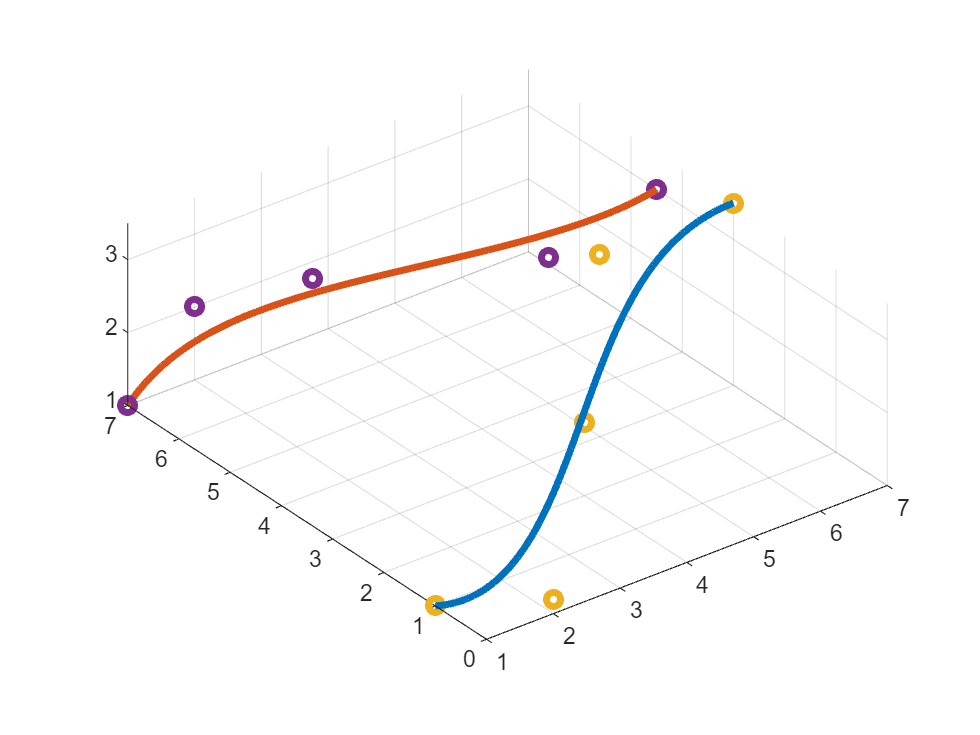

clear all 

tf = 10;
t = linspace(0,tf,1000);
]
%% 3D Bernstein Polynomials
p1_N = [1,2,4,5,7; 1,0,2,3,3; 1,1.2,2,3.5,3.5];
p2_N = [1,2,3,5,7; 7,7,6,4,4.5; 1,2,2.5,3,3];
p1N = BernsteinPoly(p1_N,t);
p2N = BernsteinPoly(p2_N,t);


% Plot
figure
plot3(p1N(1,:),p1N(2,:),p1N(3,:),'LineWidth',3); hold on
plot3(p2N(1,:),p2N(2,:),p2N(3,:),'LineWidth',3);
plot3(p1_N(1,:),p1_N(2,:),p1_N(3,:),'o','LineWidth',3);
plot3(p2_N(1,:),p2_N(2,:),p2_N(3,:),'o','LineWidth',3);
axis equal
grid on

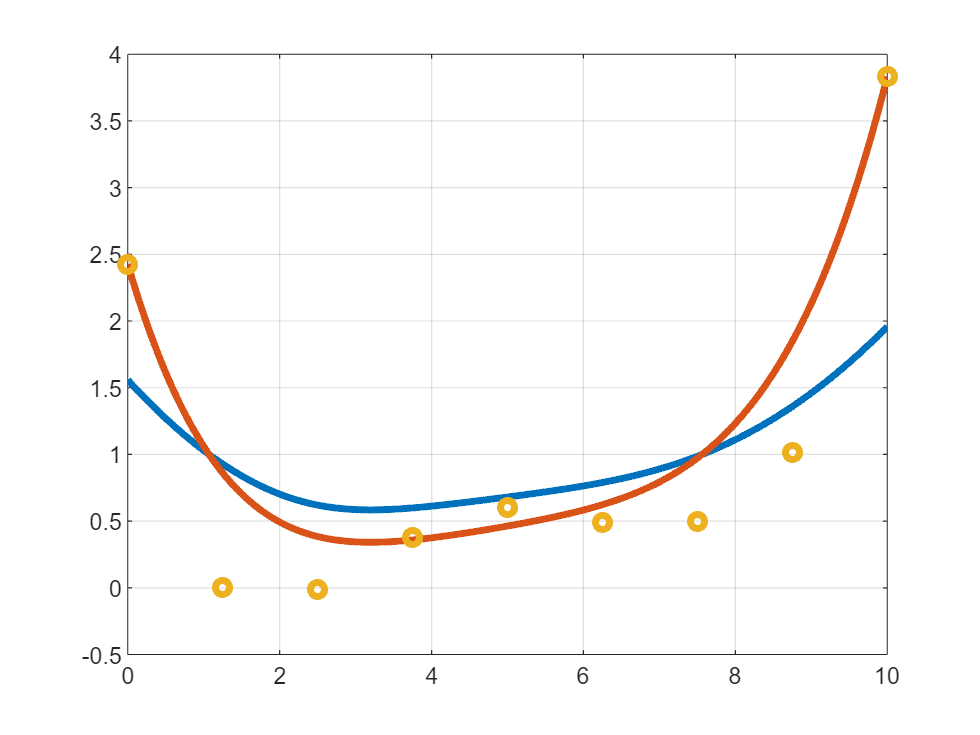



%% Speed square
[~,N] = size(p1_N);
N = N - 1;
[tnodes,w,Dm] = LGL_PS(N,tf);
p1_Ndot = p1_N*Dm;
speedsqr_2N = BernsteinProduct(p1_Ndot(1,:),p1_Ndot(1,:))+BernsteinProduct(p1_Ndot(2,:),p1_Ndot(2,:))+BernsteinProduct(p1_Ndot(3,:),p1_Ndot(3,:));
speedsqr2N = BernsteinPoly(speedsqr_2N,t);
speed2N = sqrt(speedsqr2N);


% Plot
figure
plot(t,speed2N,'LineWidth',3); hold on
plot(t,speedsqr2N,'LineWidth',3);
plot(linspace(0,tf,2*N+1),speedsqr_2N,'o','LineWidth',3);
grid on

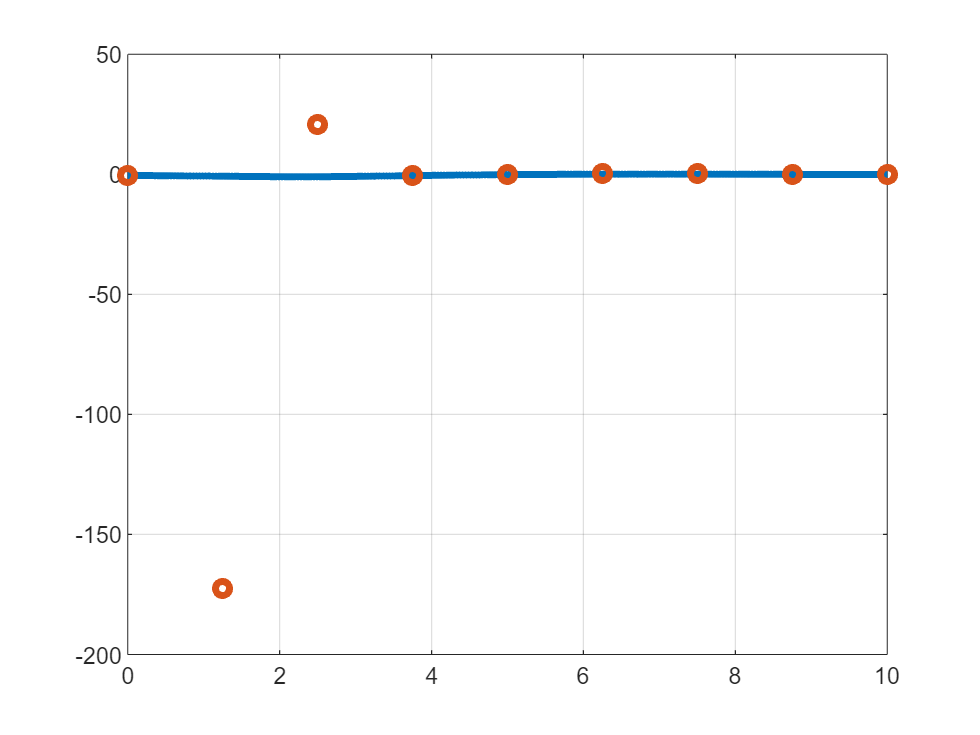



%% Psidot
p1_Nddot = p1_Ndot*Dm;
psidot_num = (BernsteinProduct(p1_Nddot(1,:),p1_Ndot(2,:))-BernsteinProduct(p1_Nddot(2,:),p1_Ndot(1,:)));
psidot_den = speedsqr_2N;
psidot_coeff = psidot_num./psidot_den;
psidot_weights = psidot_den; 
psidot = BernsteinPoly(psidot_num,t)./BernsteinPoly(psidot_den,t);

% Plot
figure
plot(t,psidot,'LineWidth',3); hold on
plot(linspace(0,tf,2*N+1),psidot_coeff,'o','LineWidth',3);
grid on

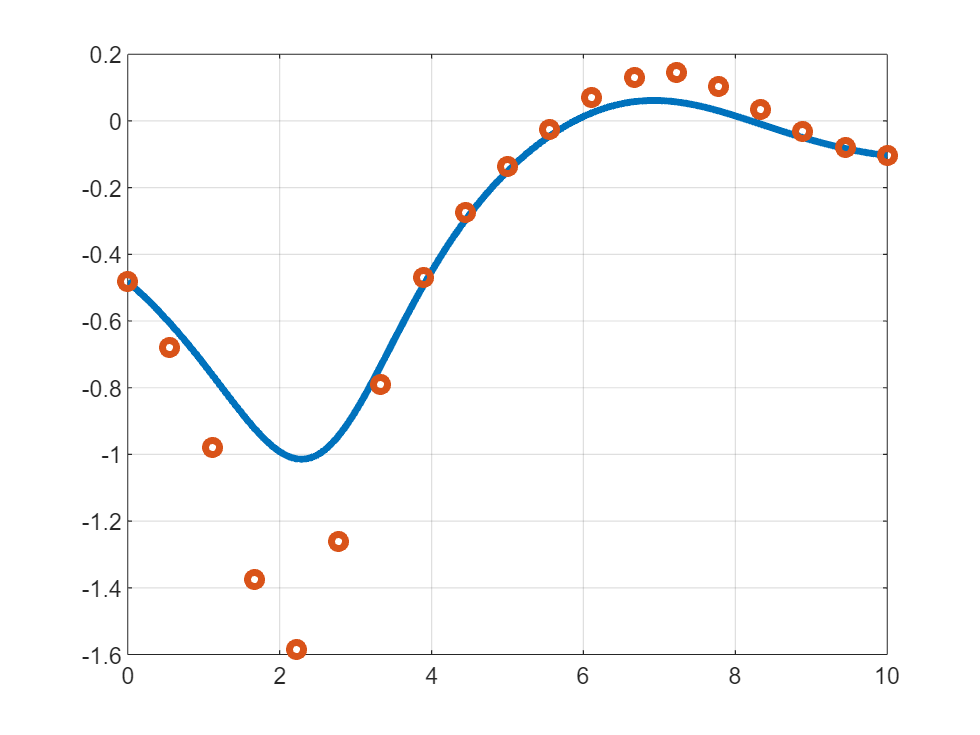



% Degree elevate
[~,N] = size(psidot_num);
N = N - 1;
psidot_num = psidot_num*DegElevMatrix(N,N+10);
psidot_den = psidot_den*DegElevMatrix(N,N+10);
psidot_coeff = psidot_num./psidot_den;
psidot_weights = psidot_den; 
psidot = BernsteinPoly(psidot_num,t)./BernsteinPoly(psidot_den,t);

% Plot
figure
plot(t,psidot,'LineWidth',3); hold on
[~,M] = size(psidot_coeff);
plot(linspace(0,tf,M),psidot_coeff,'o','LineWidth',3);
grid on

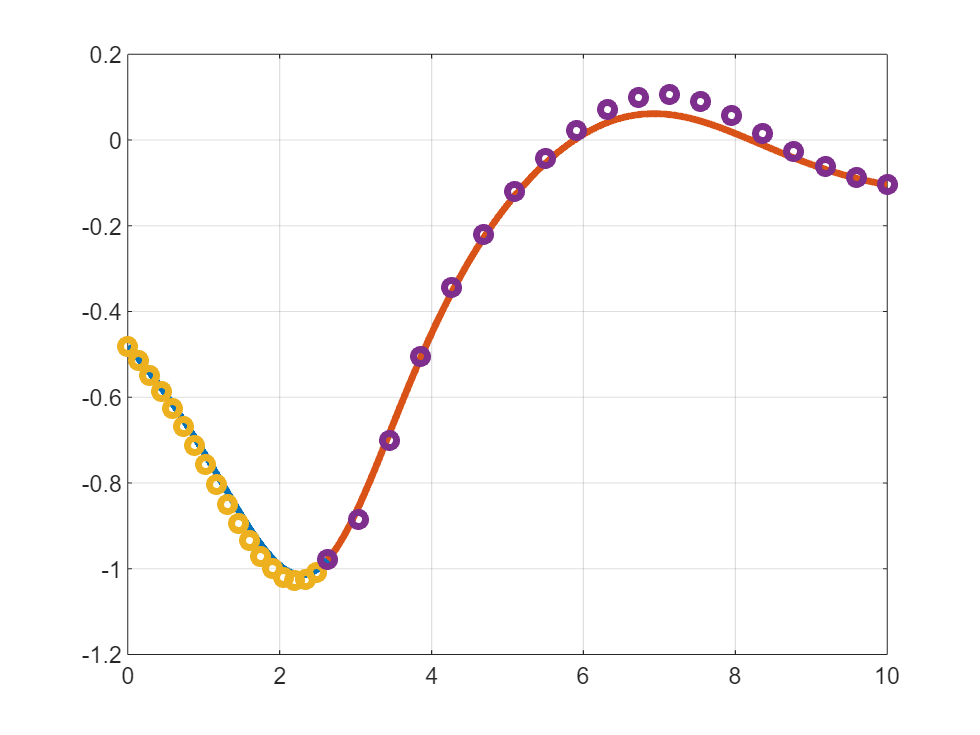



% Subdivide at min 
[minv,iminv] = min(psidot_coeff);
lambdamin = iminv/length(psidot_coeff);
[Cpnum,Pout] = deCasteljau(psidot_num,lambdamin);
[Cpden,Pout] = deCasteljau(psidot_den,lambdamin);
psidot_numA = Cpnum(:, 1:length(psidot_num(1,:)));
psidot_numB = Cpnum(:, length(psidot_num(1,:)):end);
psidot_denA = Cpden(:, 1:length(psidot_num(1,:)));
psidot_denB = Cpden(:, length(psidot_num(1,:)):end);
psidot_coeffA = psidot_numA./psidot_denA;
psidot_weightsA = psidot_denA; 
psidot_coeffB = psidot_numB./psidot_denB;
psidot_weightsB = psidot_denB; 
tA = linspace(0,lambdamin*tf,1000);
tB = linspace(lambdamin*tf,tf,1000);
psidotA = BernsteinPoly(psidot_numA,tA)./BernsteinPoly(psidot_denA,tA);
psidotB = BernsteinPoly(psidot_numB,tB)./BernsteinPoly(psidot_denB,tB);

% Plot
figure
plot(tA,psidotA,'LineWidth',3); hold on
plot(tB,psidotB,'LineWidth',3); hold on
[~,M] = size(psidot_coeffA);
plot(linspace(tA(1),tA(end),M),psidot_coeffA,'o','LineWidth',3);
plot(linspace(tB(1),tB(end),M),psidot_coeffB,'o','LineWidth',3);
grid on